# Week 13 - Solving Mazes

Solving a maze is something quite easy to do, right?! Simply trace the hallway toward the exit, and if you walk down a dead end go to the last branch and choose another! Simple in concept, but as the size of the mazes grow, humans find it very hard to keep track of which paths they have followed, and the number of paths grows exponentially....

HHhhmm... A simple task requiring massive amounts of iterations?! Maybe this problem can be better solved using computers. There are several approaches we could use to solve a maze with a computer. One example is using a massive number of "random walk" particles at the entrance, and waiting until one enxits the maze! Is there an approach which scales better?

A maze could be thought of as a hallway which already connects the entrance and the exit. The problem is that the hallways branches and turns, and any of them could be the right path out! Maybe if we knew already which were dead ends, we could not bother walking down those!

If we could test whether a given pixel was part of a path on a dead end, we could eliminate that entire path! If all dead ends were eliminated the maze is SOLVED!

In week 8 We learned about "Cellular Automata": A piece of code  which observed the state of all of the "alive" or "dead" pixels, and based on some specifically coded rules, decided whether each of those pixels was alive or dead in the next iteration. Let's use a cellular automata approach to kill cells which are in dead ends, not on a valid path

# Outlining The Code

The first thing we want to do is load in an image, and fill it's hallways with "living" cells. Then we tell matlab where the start and end points are, explicity.Next, inside of a loop, we want matlab to look at the entire maze and consider which cells should die, those which are *CERTAINLY NOT *part of our pathway, according to some specific rules which we shall decide upon, and so update the maze. The loop should execute until the maze is solved. 

Display the maze and indicate the generated path.

%         %Open up a maze, decide where the start and end-points are
%         
%         % convert the image to binary representation (B&W)
%         
%         %Fill the entire passageways with life
%         
%         
%         while done==false
%             
%             %Find out
%             %the conditions of the surrounding neighbours of a cell
%                                                                                     
%             
%             %Decide which cells should die, based on the conditions of its
%             %surrounding neighbours
%            
%                
%             %Update the maze without the dead cells
%             
%             if %The maze is solved
%                 %Exit the loop
%             end
%             
%         end
%         
%         %Trace the path over the original maze image
%         %Show the solution.


## Loading In A Maze

In the directory there is n image called "simple_maze.png". This section will import that maze then identify the walls (by eliminating "grey-ish" pixels into black or white, and then INVERT the image. (Removes walls, adds *life*)

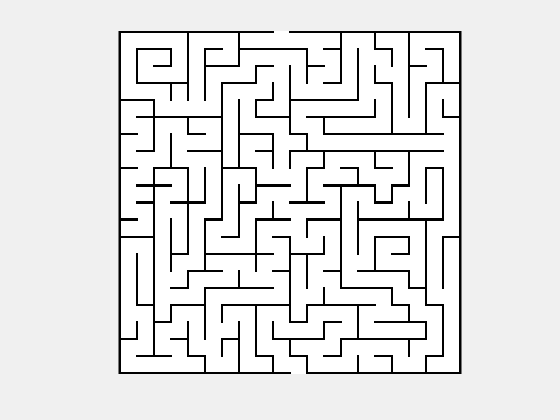

tic
%Open up a maze, with walls designated as ones and zeroes
close all
clear all
maze = imread('simple_maze.png');

%Dark/light pixels found using a threshold
hsvmaze = rgb2hsv(maze);
binmaze = hsvmaze(:,:,3) >= 0.3;

imshow(binmaze)


%Fill the entire passageways with life
A = binmaze==0;


The values below are the chosen start and end co-ordinate for 'simple_maze.png'.

start_x = 150;
start_y = 1;
end_x = 170;
end_y = 320;

Now we have a canvas, where all the hallways have been filled with "living" pixels (value of zero). Think of this maze as now being "Complete: the start and finish are now connected, all you have to do is follow the black line! WELL....using a cellular automata approach, lets reduce some of those hallways!

# Defining the conditions for life

With what kind of conditions should we kill-off a cell? How would you know if a pixel is not useful for solving a maze? Well, the pixels which are part of a path, but are serving only to make that section of the path thick...they are not useful. Once we thin the line to one-pixel, we can show the two conditions in which a pixel might be a part of a 3-pixel-long line:

There is of course the straight-line:

% n n n 
% 0 0 0 
% n n n

and a corner:

% 1 1 1
% 0 0 1
% n 0 1

...and thats ALL! Rotations of these two 3x3 grids describe all the conditions which a pixel in a line can find itself. So lets call the first condition "*is_line" * and the second "*is_corner". *

* Hmm...*. Take a look at the corner...if the neighbour labelled "*n*" were a 1, the pixel is a line, and should live...but if the neighbour were ALSO a zero...then the pixel is actually NOT part of a line, it is part of a larger block of pixels. Lets break *is_corner* into two conditions based on the value of that neighbour: If the pixel is on the OUTSIDE of a corner, but NOT part of a one-pixel-line, it should die. 

Whether that neighbour is a one or a zero, we can define "*is_an_inside_corner"* and "*is_an_outside_corner*'. A given pixel should die if it IS an outside corner, but NOT an inside corner. 

This is what the code looks like when assessing all three of these conditions:

% should_die = ((is_an_outside_corner == true)...
% &  (is_an_inside_corner==false))...
% & (is_line==false);

If a pixel is not part of a line which continues through the 3x3 moore neighbourhood, it dies.

The code for assessing whether a pixel matches any of these line & corner conditions has been provided. in the "Simulation" section, further below. Take a look and see if you agree with the conditional testing being applied. (What about the thick lines issue? there isn't an explicit death-condition to make thick lines thinner, so how do these rules create 1-dimensional lines?)

## Initialisation

The code below has been shown to you before, in Week 8! It gives us the index arrays for all the neighbour-cells. We can use these when we test the moore neighbourhood.

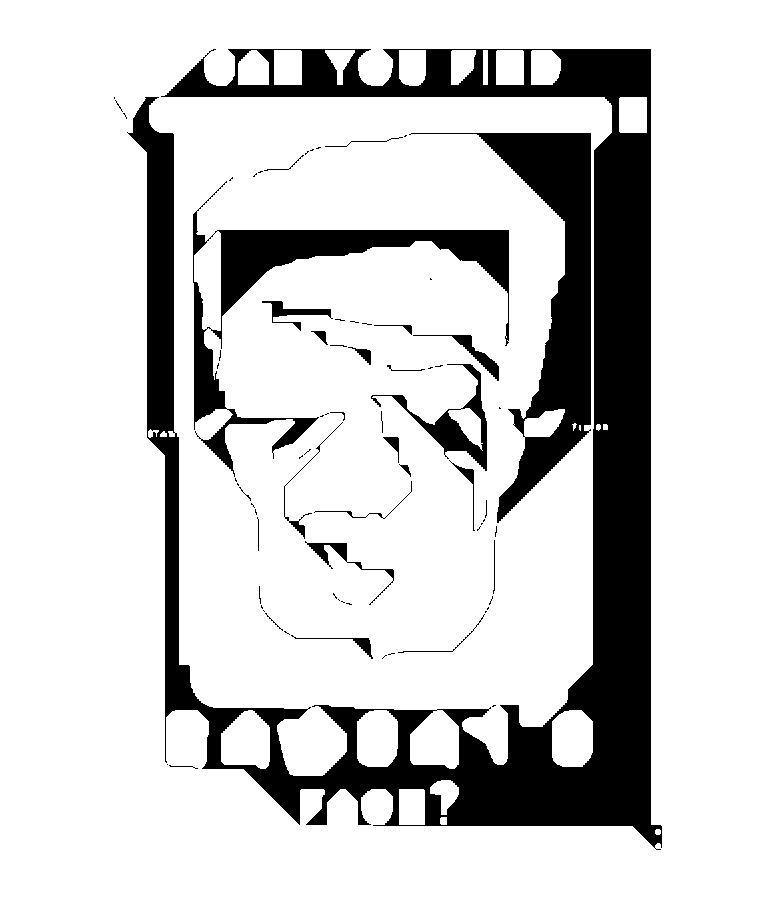

close all
mapdim = size(A);
R = mapdim(1);  % number of rows
C = mapdim(2);  % number of columns
 
north = [R,1:R-1];     % indices of north neighbour
south = [2:R,1];       % indices of south neighbour
west  = [C,1:C-1];     % indices of west neighbour
east  = [2:C,1];       % indices of east neighbour

% Show the starting frame in the animation
imshow(A)


myVideo = VideoWriter('simple_maze');
open(myVideo);


# The Simulation

Below is the loop we can use to solve the maze. It begins by setting up a variable "*done*' and iterating until done is false. First, the number of dead cells at the corners of each cell are counted. Those counts are used, as well as the conditions of specific cells in the neighbourhood, to define whether a cell matches any of our three defined conditions "*is_an_outside_corner",    "is_an_inside_corner"  *and*   "is_line". *The cells are then killed by setting them to zero (Actually, to "False" since logical matrices are analyzed so fast). The start and end cells die every single iteration, because they count as "dead ends" (They are, after all, terminations of the line). Therefore, after the loop is run it is important to** bring back to life** the start and end pixels.

To determine whether the loop should continue, the new matrix is compared against the previous to see if they are exactly the same, in which case the loop breaks.

This code includes a line to display the maze WHILE it is being solved, so the effect of the rules can be clearly seen, but since it can be hard to pause a simulation, lets record the action as well!

%% Simulation
set(figure, 'Visible', 'on');
showmaze = imshow(A, 'InitialMagnification', 'Fit');

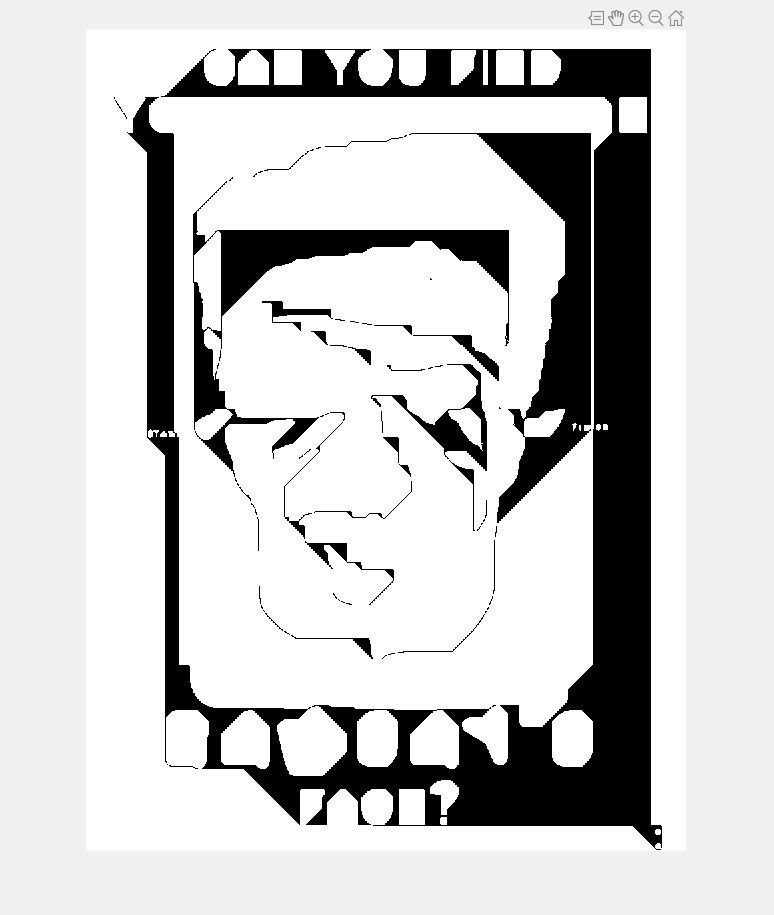

i=0;
done = false;
while done == false 
    B=A; %store a copy of the 'old" maze"
    i=i+1;
    
    % Count how many of the cells on each cardinal corner are dead cells
    NE_corner_condition = A(north, :)+ A(:, east) + A(north,east);  %     n ? ? 
    NW_corner_condition = A(north, :)+ A(:, west) + A(north,west);  %     n n ?   <-- All rotations of these
    SE_corner_condition = A(south, :)+ A(:, east) + A(south,east);  %     n n n
    SW_corner_condition = A(south, :)+ A(:, west) + A(south,west);
    
    %Test whether the cell forms a line or corner
        is_an_outside_corner =(A==false) & (...
     (A(south,:)==true &A(:, west)==true & A(south,west)==true )  ...     %     n 1 1
    |(A(south, :)==true & A(:, east) ==true & A(south,east)==true)...     %     n 0 1   <--Any rotation of this
    |(A(north, :)==true & A(:, west)==true & A(north,west)==true)...      %     n n n    
    |(A(north, :)==true & A(:, east)==true & A(north,east)==true));
    
        
        is_an_inside_corner =  (A==false)&(...
      (A(south, :)==false & A(:, west)==false & A(south,west)==true)  ...    %     n n n
    | (A(south, :)==false & A(:, east) ==false & A(south,east)==true)...     %     0 0 n   <--Any rotation of this
    | (A(north, :)==false & A(:, west)==false & A(north,west)==true)...      %     1 0 n 
    | (A(north, :)==false & A(:, east)==false & A(north,east)==true))...
    & ( NE_corner_condition == 3 |  NW_corner_condition ==3 |  SE_corner_condition ==3 |  SW_corner_condition==3);
                                                                                
                          
          is_line =  (A==false)&(...
      (A(south, :)==false & (A(north, :)==false | A(north, east) ==false | A(north, west)==false)) ... %   n n n
    | (A(:, west))==false & (A(:, east) ==false | A(north, east)==false | A(south, east)==false)) ...  %   0 0 0   <--Any rotation of this
    | (A(north, west)==false & A(south, east)==false) ...                                              %   n n n 
    | (A(north, east)==false  & A(south, west)==false);
                                                         
     
    %These three rules determine whether or not the cells should die.
    should_die = ((is_an_outside_corner == true) &  (is_an_inside_corner==false))  & (is_line==false);%| is_single;
        
    
    A = logical(A + should_die);
    A(start_y, start_x)=0;
    A(end_y, end_x)=0;
    
    if i<110 %
        showmaze.CData = A;
        drawnow
        frame = getframe;
        writeVideo(myVideo, frame);
    elseif mod(i,5)==0
        showmaze.CData = A;   
        drawnow
        frame = getframe;
        writeVideo(myVideo, frame);
    end
    if all(B==A)
        done=true;
    end
    
end 

close(myVideo)

## solved maze

Lets make sure that this matches a path through the maze! Convert our B&W image to red and paint it over the original maze.

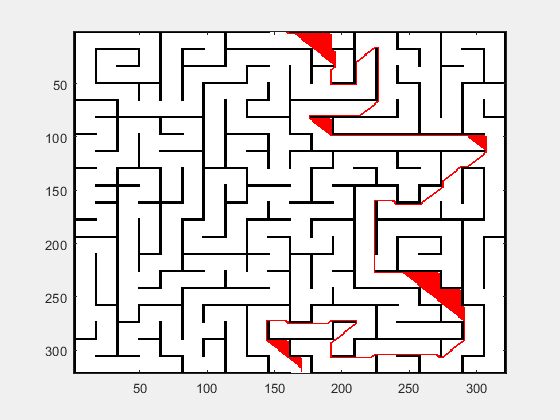

pathline = 255.*(uint8(~A));
tracedmaze1=maze;
tracedmaze1(:, :, 2:3)=tracedmaze1(:, :, 2:3)-pathline;

imagesc(tracedmaze1);

So the computed path does show the solution to the maze, although There are some residual triangles which have failed to be reduced properly.

# Complex Mazes

That simple maze had nice straight hallways with sharp angles and just one path to the exit. Let's try our simulation with a more complicated example; "gordan.jpg".

The 

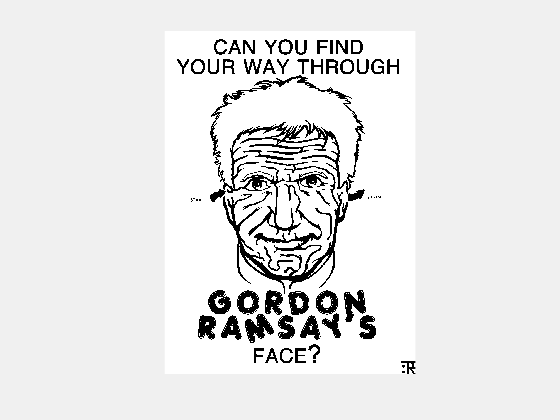

close all
clear all
maze2 = imread('gordan.jpg');

hsvmaze = rgb2hsv(maze2);
binmaze = hsvmaze(:,:,3) >= 0.3;

set(figure, 'Visible', 'on');
imshow(binmaze, 'InitialMagnification', 'Fit');


A = binmaze==0;


The values below are the chosen start and end co-ordinate for 'gordan'. 

start_x = 220;
start_y = 580;
end_x = 650;
end_y = 600;

%Outside border
A(1     ,:)=true; %Top
A(: ,end)=true; %right
A(1     ,:)=true; %bottom
A(: , end)=true; %left

%Mid-region border
A(141     ,141:760)=true; %Top
A(141:954 ,760)=true; %right
A(954     ,141:760)=true; %bottom
A(141:954 ,141)=true; %left

## Initialisation

Perform the same initializations as for the simple maze

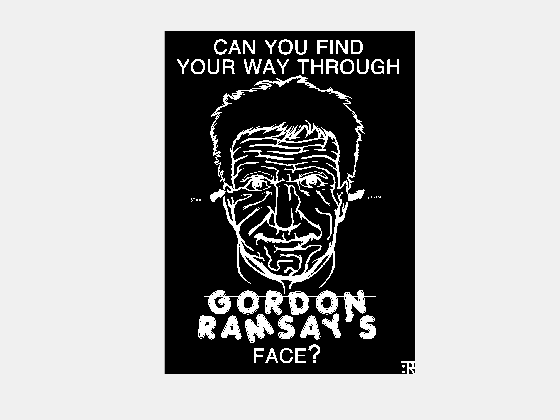

close all

mapdim = size(A);
R = mapdim(1);  % number of rows
C = mapdim(2);  % number of columns
 
north = [R,1:R-1];     % indices of north neighbour
south = [2:R,1];       % indices of south neighbour
west  = [C,1:C-1];     % indices of west neighbour
east  = [2:C,1];       % indices of east neighbour

% Show the starting frame in the animation
set(figure, 'Visible', 'on');
showmaze = imshow(A, 'InitialMagnification', 'Fit');

## Simulation

%%Simulation
tic
i=0;
done = false;
while done == false 
    B=A; %store a copy of the 'old" maze"
    i=i+1;
    % Count how many of the cells on each cardinal corner are dead cells
        
    NE_corner_condition = A(north, :)+ A(:, east) + A(north,east);
    NW_corner_condition = A(north, :)+ A(:, west) + A(north,west);
    SE_corner_condition = A(south, :)+ A(:, east) + A(south,east);
    SW_corner_condition = A(south, :)+ A(:, west) + A(south,west);
    
    %Test whether the cell forms a line or corner
        is_an_outside_corner =(A==false) & (...
     (A(south,:)==true &A(:, west)==true & A(south,west)==true )  ...     %     n 1 1
    |(A(south, :)==true & A(:, east) ==true & A(south,east)==true)...     %     n 0 1   <--Some rotation of this
    |(A(north, :)==true & A(:, west)==true & A(north,west)==true)...      %     n n n    
    |(A(north, :)==true & A(:, east)==true & A(north,east)==true));
    
        
        is_an_inside_corner =  (A==false)&(...
      (A(south, :)==false & A(:, west)==false & A(south,west)==true)  ...    %     n n n
    | (A(south, :)==false & A(:, east) ==false & A(south,east)==true)...     %     0 0 n   <--Some rotation of this
    | (A(north, :)==false & A(:, west)==false & A(north,west)==true)...      %     1 0 n 
    | (A(north, :)==false & A(:, east)==false & A(north,east)==true))...
    & ( NE_corner_condition == 3 |  NW_corner_condition ==3 |  SE_corner_condition ==3 |  SW_corner_condition==3);
                                                                                
                          
          is_line =  (A==false)&(...
      (A(south, :)==false & (A(north, :)==false | A(north, east) ==false | A(north, west)==false)) ... %   n n n
    | (A(:, west))==false & (A(:, east) ==false | A(north, east)==false | A(south, east)==false)) ...  %   0 0 0   <--Some rotation of this
    | (A(north, west)==false & A(south, east)==false) ...                                              %   n n n 
    | (A(north, east)==false  & A(south, west)==false);
                                                         
     
    %These three rules determine whether or not the cells should die.
    should_die = ((is_an_outside_corner == true) &  (is_an_inside_corner==false))  & (is_line==false);%| is_single;

    A = logical(A + should_die);
    A(start_y, start_x)=false;
    A(end_y, end_x)=false;
    
    
%    % Uncomment to see Gordan Ramsey's face melting
%     if i<110 %
%       showmaze.CData = A;
%       drawnow
%     elseif mod(i,150)==0
%       showmaze.CData = A;
%       drawnow
%     end
    
    if all(B==A)
        done=true;
    end
    
end 
toc

## solved maze

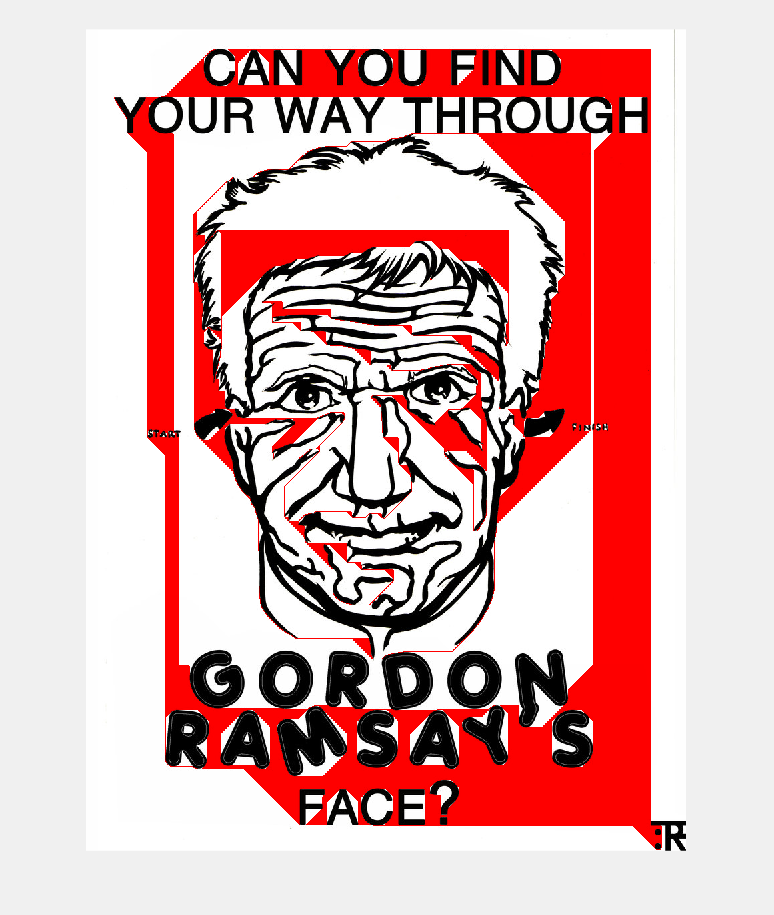

pathline = 255.*(uint8(~A));
tracedmaze2=maze2;
tracedmaze2(:, :, 2:3)=tracedmaze2(:, :, 2:3)-pathline;

imshow(tracedmaze2);

Has this satisfactorily solved the maze? There are a lot of red lines and regions on the image which have nothing to do with the solution.

However, if you follow the red path from the * starting point *, all of the red lines from there are viable solutions to the maze! The maze solver has kept in all alternate paths (Loops) within the maze, and has even indicated that going AROUND the face in either direction is a viable path.

# A better maze solver!

This maze solver works well with complex mazes and scales well because it doesn't depend on testing dead-end paths. It even works well with large images. As with many automation programs, this program is able to do well, what humans do badly (Accurately and repeatedly analysing large arrays) while humans do well what this program fails at (recognizing that empty areas outside of the maze are not worth exploring for solutions). 

If an extremely large maze were needed to be solved, there is a lot of room left to improve this code!. For example, 99% of the run-time of the code is committed to building the arrays for *is_line, is_inside_corner & is_outside corner*. If these could be distilled to one or two (instead of three) the runtime would be cut down by half, or a third. Or, perhaps the red triangles which get left over are a nuisance, in which case a FOURTH rule might be added so that these are always eliminated. Or a sub-routine could include searching for bounded regions which have just one path crossing the boundary, meaning that path terminates (dead end) within the region, allowing that entire region to be "killed"

 And perhaps you could use solution of this solver in another which decides which loops could be eliminated, yielding only the single most efficient path


%%Errors and Notes%% 

% Our original concept for the maze solver was to use random walks to solve it,
% however once we started we found that cellular Automata was a better fit for
% what we were trying to achieve.

% We have twow arning types in the code:
% 
% One is about 'CLEAR ALL' slowing down the code.
% We feel this is acceptable to leave in as clear all is used only twice,
% to ensure a clean workspace
%
% The second is a false warning: MATLAB think that the showmaze
% functionality is unused: Instead it is inside an "if" statement which
% always executes.

% Both mazes suffer from a turning error that leaves the solution with several 
% wide corners left in. With additional conditions added to the simulation section
% this could be eliminated, however this will also increase run time.

% The maze 'gordan' suffers from excess noise that causes 'islands', isolated 
% pixels inside of walls that our code will not solve for. with more nuanced 
% image conversion a cleaner mask could be generated limiting or eliminating 
% this factor.

Elapsed time is 164.704711 seconds.
